# Iterative Closest Point Algorithm

Robotics, Vision & Control: (c) Peter Corke 1992-2011 http://www.petercorke.com
- Robotics Toolbox for MATLAB (release 10.2)


 - ARTE contributed code: 3D models for robot manipulators (C:\Users\Andy\Documents\MATLAB\Add-Ons\Toolboxes\Robotics Toolbox for MATLAB\code\robot\data\ARTE)
 - pHRIWARE (release 1.1): pHRIWARE is Copyrighted by Bryan Moutrie (2013-2018) (c)
Run rtbdemo to explore the toolbox


principal point not specified, setting it to centre of image plane


creating new figure for camera


h =   Axes (noname) with properties:

             XLim: [0 1280]
             YLim: [0 1024]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


make axes


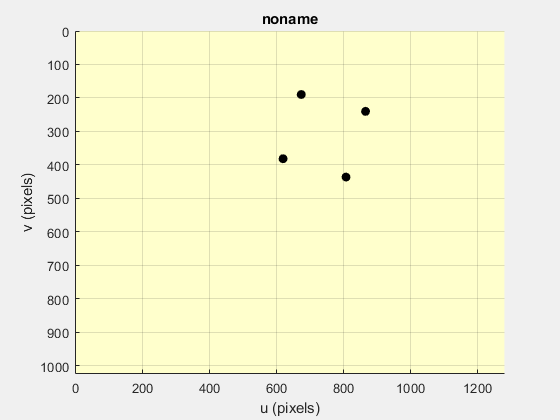

maximum residual 2.344e-13


 

cTt = 
    0.9363   -0.2751    0.2184       0.1
    0.2896    0.9564   -0.0370      -0.2
   -0.1987    0.0978    0.9752       1.5
         0         0         0         1


cTt_estimate =     0.9363   -0.2751    0.2184    0.1000
    0.2896    0.9564   -0.0370   -0.2000
   -0.1987    0.0978    0.9752    1.5000
         0         0         0    1.0000


startup_rvc;

- using peter corkes library for SE3 conversions

Setup two point clouds, P and Q, separated by a transformation matrix `qTp`.

qTp = SE3(0.1, -0.2, 1.5) * SE3.rpy(0.1, 0.2, 0.3);
N = 20;
P = randn(3, N);
Qh = qTp.T*e2h(P);
Q = h2e(Qh);

**Part a:** Create `pq2tr `function, run it on the two point clouds and compare result ot `qTp`.

T = pq2tr(P, Q)

T =     0.9363   -0.2751    0.2184    0.1000
    0.2896    0.9564   -0.0370   -0.2000
   -0.1987    0.0978    0.9752    1.5000
         0         0         0    1.0000


qTp

 

qTp = 
    0.9363   -0.2751    0.2184       0.1
    0.2896    0.9564   -0.0370      -0.2
   -0.1987    0.0978    0.9752       1.5
         0         0         0         1


Match Confirmed.

**Part b:** Relax our assumption that we know the correspondances for each pair of points between the two clouds.

Pr = P(:, randperm(N));
Qr = Q(:, randperm(N));

Use the `closest` algorithm to determine the closest points between the two data sets.

corresp = closest(Pr, Qr);
[Pr_closest,Qr_closest] = unique_pairs(Pr, Qr, corresp);

Run `pq2tr` again on this permutation of the point clouds.

Tb = pq2tr(Pr_closest, Qr_closest)

Tb =     0.9928    0.0210   -0.1181    0.0506
   -0.0105    0.9960    0.0890    0.0329
    0.1195   -0.0871    0.9890    0.4056
         0         0         0    1.0000


Here we see that Tb is different than the actual transformation matrix because the structural information that relates points from one cloud to the next is lost. Instead of using this exact correspondance, we are instead just estimating a transition matrix to move the cloud in a manner that reduces the distance between the closest point pairs. This is an insufficient method to finding the exact transformation between the two point clouds, and will require an iterative process that uses this estimate to move the point cloud `Pr` to this new position where the process can then be repeated and hopefully are larger subset of the point pairs can be deemed 'closest' to each other and therefore give a better representation of the true point correspondance based on the structure of the cloud.

**Part c: **corresp = closest(Pr, Qr); Implement `icp_simple` that runs `pq2tr` multiple times to give a better estimate of the transition matrix.

Tc = icp_simple(Pr, Qr, 10)

Iteration: 1
    Current mean distance:  0.92331
Iteration: 2
    Current mean distance:  0.86497
Iteration: 3
    Current mean distance:  0.79068
Iteration: 4
    Current mean distance:  0.54581
Iteration: 5
    Current mean distance:  0.067627
Iteration: 6
    Current mean distance:  1.2202e-15
Iteration: 7
    Current mean distance:  1.3411e-15
Iteration: 8
    Current mean distance:  1.3761e-15
Iteration: 9
    Current mean distance:  1.3751e-15
Iteration: 10
    Current mean distance:  1.5403e-15


Tc =     0.9363   -0.2751    0.2184    0.1000
    0.2896    0.9564   -0.0370   -0.2000
   -0.1987    0.0978    0.9752    1.5000
         0         0         0    1.0000


Here we have seen that the mean distance between the point clouds had rapidly decreased even within 10 iterations of the ICP algorithm. Additionally, the `Tc` variable representing the true estimate of the transition matrix matches `qTp`.